clear;

% Input parameters
Power = 800 * 1e3;               % Power in Watt
S = 800 - 495.7851j;             % Complex power
S_Conjugate = 800 + 495.7851j;   % Complex power Conjugate
PF = 0.85;                       % Power Factor
L = 160;                         % Route Length in Km
f = 60;                          % Frequency in Hz
Power_angle_max = 30 * pi / 180; % Power angle in Rad
Conductor_Spacing = 8;           % Conductor Spacing in meters
Bundle_Spacing = 0.45;           % Bundle Spacing in meters
VR_Maximum = 0.1;                % Voltage Regulation Percentage
Power_Loss_Max = 100 * 1e3;      % Maximum Power Loss in Watt

% Properties Table
Voltage_options = [345; 500; 765];      % Transmission Voltage (kV)
Reactance = [0.3; 0.32; 0.27];          % Reactance per km (Ohms/km)
k_range = {[2]; [2; 3; 4]; [3; 4]};     % Range of k values as arrays

% Display voltage and reactance data
disp('Transmission Data:');

Transmission Data:


disp(table(Voltage_options, Reactance, 'VariableNames', {'Voltage_kV', 'Reactance_per_km_Ohm'}));

    Voltage_kV    Reactance_per_km_Ohm
    __________    ____________________

       345                 0.3        
       500                0.32        
       765                0.27        




% Results storage
Results = [];

% Loop through each voltage level and its corresponding k_range
for i = 1:length(Voltage_options)
    Voltage_V = Voltage_options(i) * 1e3;  % Convert to volts
    k_values = k_range{i};                % Extract k values for this voltage level
    
    for k = k_values' % Loop through each k value for the current voltage level
        % Calculate Line Current
        LineCurrent = S_Conjugate * 1000 / (sqrt(3) * Voltage_V);
        
        % Calculate Minimum Number of Circuits
        Num_Circuits_Minimum = 1 + ceil((L * Reactance(i) * Power) / ...
                                        (Voltage_V^2 * sin(Power_angle_max)));
        
        % Calculate Current per Bundle
        I_b = LineCurrent / (Num_Circuits_Minimum * k);
        
        % Store results in a row
        Results = [Results; Voltage_options(i), k, LineCurrent, Num_Circuits_Minimum, I_b];
    end
end

% Create results table
ResultsTable = array2table(Results, ...
    'VariableNames', {'Voltage_kV', 'k', 'Line_Current', 'Num_Circuits_Minimum', 'Bundle_Current'});
disp('Results:');

Results:


disp(ResultsTable);

    Voltage_kV    k      Line_Current      Num_Circuits_Minimum      Bundle_Current  
    __________    _    ________________    ____________________    __________________

       345        2     1.3388+0.82969i             2                0.3347+0.20742i 
       500        2    0.92376+0.57248i             2               0.23094+0.14312i 
       500        3    0.92376+0.57248i             2               0.15396+0.095414i
       500        4    0.92376+0.57248i             2               0.11547+0.07156i 
       765        3    0.60376+0.37417i             2               0.10063+0.062362i
       765        4    0.60376+0.37417i             2              0.075471+0.046772i




% Additional parameters from the provided table
Materials = {'Linnet', 'Wedgion', 'Merlin', 'Piper', 'Waxwing'};
Resistance_AC = [178.8, 173.7, 173.0, 195.0, 218.1] * 1e-3; % Resistance in Ohms/km
GMR_values = [7.41, 7.05, 6.74, 7.05, 6.00] * 1e-3;       % GMR in meters
D1 = 8;
D2 = 16;
GMD = (D1 * D2 * D1)^(1/3); % Geometric Mean Distance

% Constants
mu_0 = 4 * pi * 1e-7; % Permeability of free space (H/m)
epsilon_0 = 8.854e-12; % Permittivity of free space (F/m)

% Calculate Inductance, Capacitance, and ABCD parameters
Inductance = zeros(length(Materials), 1);
Capacitance = zeros(length(Materials), 1);
A = zeros(length(Materials), 1);
B = zeros(length(Materials), 1);
C = zeros(length(Materials), 1);
D = zeros(length(Materials), 1);

for i = 1:length(Materials)
    % Extract resistance and GMR
    R = Resistance_AC(i); 
    GMR = GMR_values(i);
    
    % Inductance per unit length (H/m)
    Inductance(i) = (mu_0 / (2 * pi)) * log(GMD / GMR);
    
    % Capacitance per unit length (F/m)
    Capacitance(i) = (2 * pi * epsilon_0) / log(GMD / GMR);
    
    % Inductive and Capacitive Reactances
    XL = 2 * pi * f * Inductance(i) * L; % Ohm
    XC = 1 / (2 * pi * f * Capacitance(i) * L); % Ohm
    
    % ABCD Parameters (Medium Pi Model)
    z = R + 1j * XL;                        % Total impedance
    y = 1j * 2 * pi * f * Capacitance(i);   % Total admittance
    Z = z * L;                              % Total impedance over the line
    Y = y * L;                              % Total admittance over the line
    
    A(i) = 1 + (Z * Y) / 2;
    B(i) = Z;
    C(i) = Y * (1 + (Z * Y) / 4);
    D(i) = A(i);
end

% Display Results
disp('Inductance (H/m):');

Inductance (H/m):


disp(Inductance);

   1.0e-05 *

    0.1443
    0.1453
    0.1462
    0.1453
    0.1485




disp('Capacitance (F/m):');

Capacitance (F/m):


disp(Capacitance);

   1.0e-11 *

    0.7710
    0.7657
    0.7610
    0.7657
    0.7491




ABCD_Table = table(Materials', A, B, C, D, ...
    'VariableNames', {'Material', 'A', 'B', 'C', 'D'});
disp('ABCD Parameters:');

ABCD Parameters:


disp(ABCD_Table);

     Material            A                B                      C                     D      
    ___________    _____________    ______________    _______________________    _____________

    {'Linnet' }    1+6.6522e-06i    28.608+13.927i    -1.5468e-12+4.6506e-07i    1+6.6522e-06i
    {'Wedgion'}    1+6.4182e-06i    27.792+14.023i    -1.4822e-12+4.6187e-07i    1+6.4182e-06i
    {'Merlin' }    1+6.353e-06i      27.68+14.11i     -1.4581e-12+4.5903e-07i    1+6.353e-06i 
    {'Piper'  }    1+7.2052e-06i      31.2+14.023i    -1.6639e-12+4.6187e-07i    1+7.2052e-06i
    {'Waxwing'}    1+7.8837e-06i    34.896+14.335i    -1.7811e-12+4.5184e-07i    1+7.8837e-06i




% Extract columns from ABCD_Table
Materials_Array = ABCD_Table.Material;  % Materials as a cell array
A_Array = ABCD_Table.A;                 % A column as an array
B_Array = ABCD_Table.B;                 % B column as an array
C_Array = ABCD_Table.C;                 % C column as an array
D_Array = ABCD_Table.D;                 % D column as an array

% Extract data from ResultsTable
Voltage_Array = ResultsTable.Voltage_kV * 1000; % Convert kV to V
LineCurrentArray = ResultsTable.Line_Current;   % Line current array
% Define transmitted power (800 MW assumed)
power_trans = 800 * 1e6; % Transmitted Power in Watts (800 MW)

% Initialize the results table
Table_Results = table();

% Loop through each voltage and material
for i = 1:length(Voltage_Array)
    for j = 1:length(Materials_Array)
        % Calculate V_Sending and I_Sending using LineCurrentArray
        V_Sending = (A_Array(j) * Voltage_Array(i) / sqrt(3)) + ...
                    (B_Array(j) * LineCurrentArray(i));
        I_Sending = (C_Array(j) * Voltage_Array(i)) + ...
                    (D_Array(j) * LineCurrentArray(i) * (10^3));

        % Calculate Power Factor (pf_sending)
        pf_sending = cosd(rad2deg(angle(I_Sending)) - rad2deg(angle(V_Sending)));

        % Calculate Power (Ps) in Watts
        Ps = 3 * abs(I_Sending) * abs(V_Sending) * pf_sending; % in Watts
        P_loss = (Ps - power_trans)/ 1e3; % Power loss in Watts
        Ps_MW = (800 - P_loss) ;  % Convert to MW after accounting for power loss

        % Calculate No-load Voltage (V_no_load)
        V_no_load = (abs(V_Sending) * sqrt(3)) / abs(A_Array(j));

        % Calculate Voltage Regulation (VRegulation)
        V_load = Voltage_Array(i);  % Full load voltage
        VRegulation = 1000 * (V_no_load - V_load) / V_load;

        % Efficiency calculation
        efficiency = Ps_MW/800 * 100; % Efficiency in percentage

        % Add to the results table
        new_row = table(string(Materials_Array{j}), Voltage_Array(i), Ps_MW, VRegulation, efficiency, P_loss , ...
        'VariableNames', {'Material', 'Voltage', 'Power_MW', 'Voltage_Regulation', 'Efficiency', 'Power_Loss_MW'});
        Table_Results = [Table_Results; new_row];
    end
end

% Display the table
disp('Results Table:');

Results Table:


disp(Table_Results);

    Material     Voltage     Power_MW    Voltage_Regulation    Efficiency    Power_Loss_MW
    _________    ________    ________    __________________    __________    _____________

    "Linnet"     3.45e+05     592.26           0.13429           74.032         207.74    
    "Wedgion"    3.45e+05     598.33           0.12841           74.791         201.67    
    "Merlin"     3.45e+05     599.16           0.12729           74.895         200.84    
    "Piper"      3.45e+05     572.96           0.15132           71.621         227.04    
    "Waxwing"    3.45e+05     545.46           0.17487           68.182         254.54    
    "Linnet"        5e+05      703.8          0.063932           87.975         96.204    
    "Wedgion"       5e+05     706.69           0.06113           88


% Filter designs based on Power Factor and Efficiency
Filtered_Results = Table_Results(Table_Results.Voltage_Regulation < 10 & ...
                                 Table_Results.Efficiency > 90, :);

% Sort filtered results by Voltage and Material (ascending order)
Sorted_Results = sortrows(Filtered_Results, {'Voltage', 'Material'});

% Select the best three designs
Best_Three_Designs = Sorted_Results(1:min(3, height(Sorted_Results)), :);

% Display the top three designs
disp('Best Three Designs:');

Best Three Designs:


disp(Best_Three_Designs);

    Material    Voltage     Power_MW    Voltage_Regulation    Efficiency    Power_Loss_MW
    ________    ________    ________    __________________    __________    _____________

    "Linnet"    7.65e+05     761.86           0.02731           95.232         38.142    
    "Linnet"    7.65e+05     761.86           0.02731           95.232         38.142    
    "Merlin"    7.65e+05     763.26          0.025886           95.408         36.737    



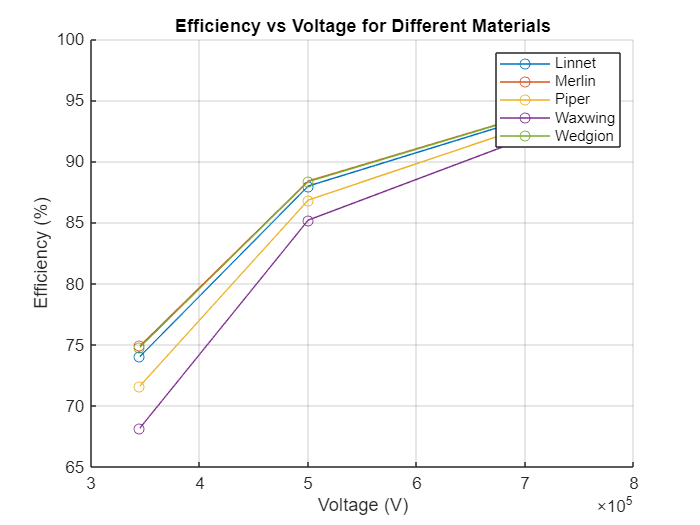


% Extract unique materials
materials = unique(Table_Results.Material);

figure;
hold on;
for i = 1:length(materials)
    % Filter data for each material
    material_data = Table_Results(strcmp(Table_Results.Material, materials{i}), :);
    
    % Plot Efficiency vs Voltage
    plot(material_data.Voltage, material_data.Efficiency, '-o', 'DisplayName', materials{i});
end
hold off;
grid on;
title('Efficiency vs Voltage for Different Materials');
xlabel('Voltage (V)');
ylabel('Efficiency (%)');
legend('show');